Creates a correction for the autocorrelation based on the changing initiation rates

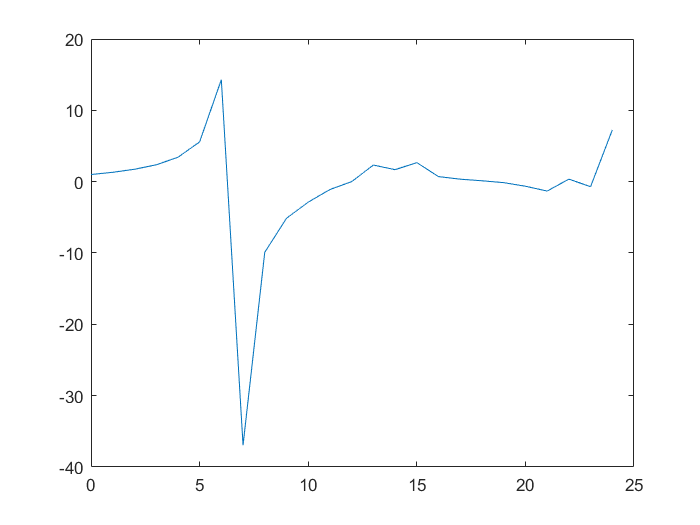

elong_time = 200;
time_res = 20;
points_per_trace = 50;
num_traces = 100;
num_states = 3;
trans_mat = [-0.0115,  0.0095,  0.0000; ...
         0.0115, -0.0180,  0.0440; ...
         0.0000,  0.0085, -0.0440];
rna_per_sec = [2, 65, 130];
fluo_per_rna = 350;
MS2_rise_times = 0;
init_dist = [1,0,0];
noise = 0;
max_delay = 25;
traces = gen_data(elong_time, time_res, points_per_trace, ...
    num_traces, num_states, trans_mat, rna_per_sec, ...
    fluo_per_rna, MS2_rise_times, init_dist, noise);
init_traces = get_correction(time_res, points_per_trace, ...
    num_traces, num_states, trans_mat, rna_per_sec, init_dist);

norm_cor = auto_corr_m_calc_norm(traces, max_delay);
init_cor = auto_corr_m_calc_norm(init_traces, max_delay);
corr = norm_cor ./ init_cor;
deriv1 = corr(2:end) - corr(1:end-1);
deriv2 = deriv1(2:end) - deriv1(1:end-1);

figure();
plot(0:length(corr) - 1, corr);

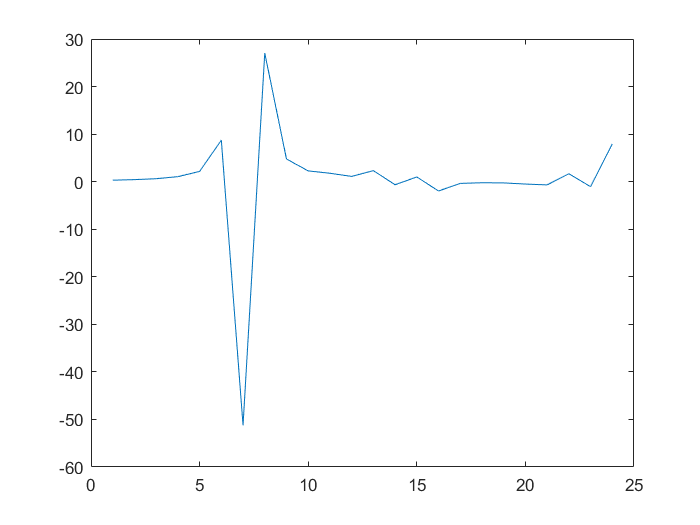

figure();
plot(deriv1);

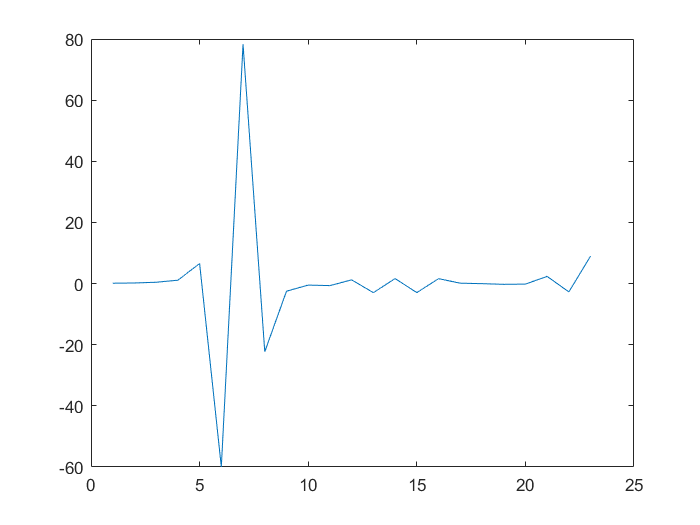

figure();
plot(deriv2);